# ME766A: Assignment-2

Name: Kartikeya Gupta

Roll No: 190420

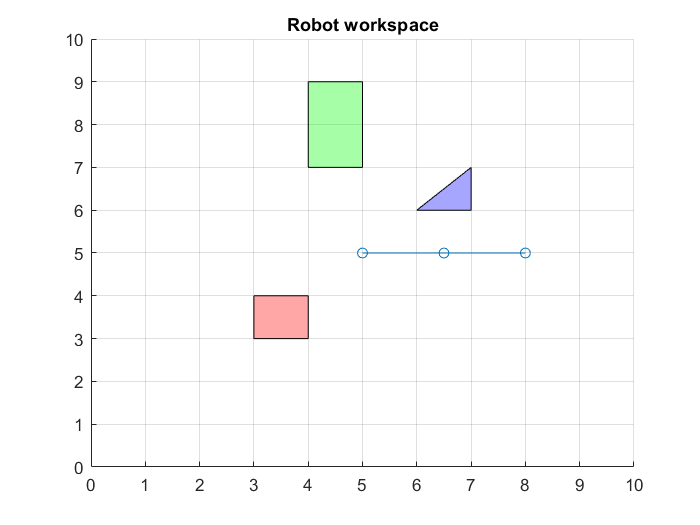

% Instructions for running the programme
% **********************************************
% The programme has functions from the Mapping
% Toolbox of MATLAB. You first need to install
% it. 
% Then simply run the programme to visualize the
% results.
% Also, note that the current program has iterations
% of 10 degrees. This has been done to reduce the
% total runtime of the simulation.
% In case better configurations are available, the 
% simualtion can be made for 1 degree iteration as
% well.
%************************************************

% Defining obstacles in the workspace
pgon1 = polyshape([3 3 4 4],[3 4 4 3]);
pgon2 = polyshape([6 7 7],[6 6 7]);
pgon3 = polyshape([4 5 5 4], [7 7 9 9]);

% Initial parameters for the 2DOF robot
arm_legnth = 1.5;
origin = [5,5];

f1 = figure;
f2 = figure;
f3 = figure;

% Plotting the workspace with the obstacles 
% and simulating the torus formation
figure(f3)
axis([0 10 0 10])
title("Robot workspace")
hold on
grid on
scatter([5 6.5 8],[5 5 5])
line([5 6.5],[5 5])
line([6.5 8],[5 5])
plot(pgon1,'Facecolor', 'r')
plot(pgon2, 'Facecolor', 'b')
plot(pgon3, 'Facecolor', 'g')
hold off

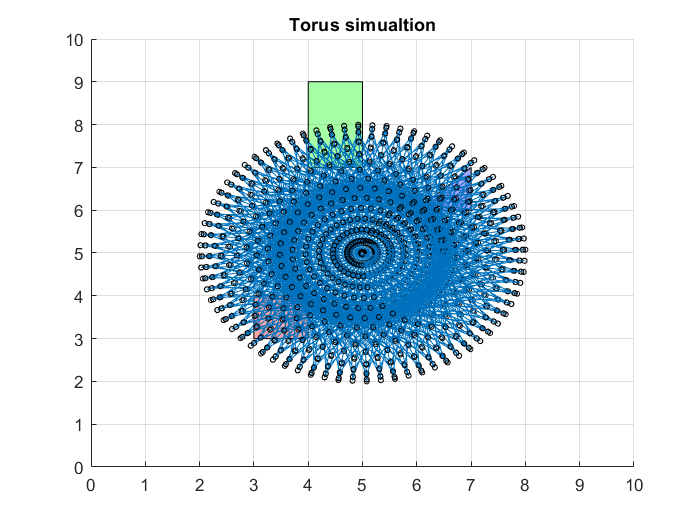

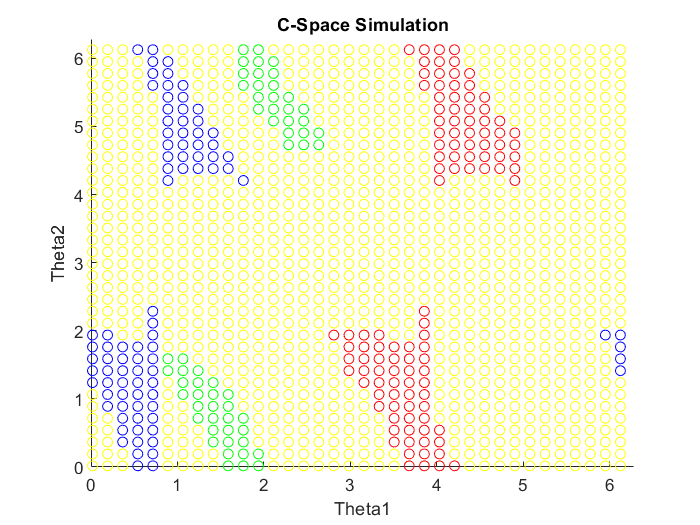



figure(f1)
axis([0 10 0 10])
title("Torus simualtion")
hold on
grid on
plot(pgon1,'Facecolor', 'r')
plot(pgon2, 'Facecolor', 'b')
plot(pgon3, 'Facecolor', 'g')
hold off

% Simulating the C-space formation
figure(f2)
title("C-Space Simulation")
hold on
xlabel("Theta1")
ylabel("Theta2")
axis([0 2*pi 0 2*pi])


for theta1=1:10:360
    [x1,y1] = calcCoordJoint1(theta1,arm_legnth,origin);
    for theta2=1:10:360
        [x2,y2] = calcCoordJoint2(theta1,arm_legnth, theta2, arm_legnth,origin);
        lineseg = [x1 y1;x2 y2];
        
        % Plotting the torus
        figure(f1)
        hold on
        scatter(x2,y2,10,"black");
        line([x1 x2],[y1 y2]);
        hold off
        
        % Checking the intersection with obstacle 1
        [in,~] = intersect(pgon1,lineseg);
        if not(isempty(in))
            figure(f2)
            scatter(deg2rad(theta1), deg2rad(theta2),'red');
            continue;
        end
        
        % Checking the intersection with obstacle 2
        [in,~] = intersect(pgon2,lineseg);
        if not(isempty(in))
            figure(f2)
            scatter(deg2rad(theta1), deg2rad(theta2),'blue');
            continue;
        end
        
        % Checking the intersection with obstacle 3
        [in,~] = intersect(pgon3,lineseg);
        if not(isempty(in))
            figure(f2)
            scatter(deg2rad(theta1), deg2rad(theta2),'green');
            continue;
        end
        
        figure(f2)
        scatter(deg2rad(theta1), deg2rad(theta2),'yellow');
        
        pause(0.001);    
    end
end

function [x,y] = calcCoordJoint1(theta, arm_length, origin)
    x = origin(1,1) + arm_length*cos(deg2rad(theta));
    y = origin(1,2) + arm_length*sin(deg2rad(theta)); 
end

function [x,y] = calcCoordJoint2(theta1, arm_length1, theta2, arm_length2,origin)
    x = origin(1,1) + arm_length1*cos(deg2rad(theta1)) + arm_length2*cos(deg2rad(theta1+theta2));
    y = origin(1,2) + arm_length1*sin(deg2rad(theta1)) + arm_length2*sin(deg2rad(theta1+theta2)); 
end